clear all;
close all;
clc;
%start time is Jun 12 2020 12:00:00
startTime = 20200612120000;
%end time is Jun 18 2020 17:00:00
endTime = 20200618170000;
%stn 067
stnID = 067;

freqTable = readtable('San_Nic_Jun2020.txt');

%edit start and end times because frequency band energies are to 30 min precision
startTime = int2str(startTime);
startTime = str2num(startTime(1:12));
endTime = int2str(endTime);
endTime = str2num(endTime(1:12));    
%collecting times from frequency band table
t_energy = freqTable{:,1};
start_index = find(t_energy == startTime);
end_index = find(t_energy == endTime);
t_energy = t_energy(start_index:end_index);   
% energies for each frequency band 
energies = freqTable{start_index:end_index,4:12};

%start time is Jun 12 2020 12:00:00
startTime = 20200612120000;
%end time is Jun 18 2020 17:00:00
endTime = 20200618170000;

cdipid = stnID; 
%convert startTime for cdip
    startTimestr = int2str(startTime);
    y_start = str2num(startTimestr(:,1:4));
    m_start = str2num(startTimestr(:,5:6));
    d_start = str2num(startTimestr(:,7:8));
    h_start = str2num(startTimestr(:,9:10));
    min_start = str2num(startTimestr(:,11:12));
    s_start = str2num(startTimestr(:,13:14));
    %convert endTime
    endTimestr = int2str(endTime);
    y_end = str2num(endTimestr(:,1:4));
    m_end = str2num(endTimestr(:,5:6));
    d_end = str2num(endTimestr(:,7:8));
    h_end = str2num(endTimestr(:,9:10));
    min_end = str2num(endTimestr(:,11:12));
    s_end = str2num(endTimestr(:,13:14));

tlims = [datenum(y_start,m_start,d_start,h_start,min_start,s_start) datenum(y_end, m_end,d_end,h_end,min_end,s_end)]; 

% spectral data etc. ------------------------------------------------------
clear cdip;
tres = 1;

varnm = 'Time';
[cdip.time] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Hs';
[cdip.hs] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Tp';
[cdip.tp] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'EnergyDensity';
[cdip.sf, cdip.f] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'MeanDirection';
[cdip.md] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime


max_period = 6;
min_period = 2;
%find indices of desired frequency rannge
indices = find(cdip.f >= 1/max_period & cdip.f <= 1/min_period);
%temporary
newband = NaN(length(cdip.time),1);
sum = 0;
%loop through each time
for i = 1:length(newband)
    %loop through each frequency within range
    for j = 1:length(indices)-1
        %frequency difference
        d_f = cdip.f(indices(j+1)) - cdip.f(indices(j));
        %average energy
        d_e = cdip.sf(j,i);
        %add product to running sum
        sum = sum + d_f*d_e;
    end
    %correction to make energy in cm
    newband(i) = sum*10000;
    sum = 0;
end

variance = trapz(cdip.f(indices),cdip.sf(indices,:))*10000

variance = 	1.0e+03 *

    0.3081    0.2970    0.2767    0.2477    0.2683    0.2157    0.2850    0.3014    0.3105    0.3001    0.2802    0.3177    0.2587    0.3597    0.3516    0.4095    0.4664    0.5416    0.5405    0.5728    0.7831    0.7935    0.7200    0.7968    0.9220    0.8730    0.9436    1.0197    1.1244    1.1823    1.1672    1.2125    1.1488    1.0802    1.2191    1.2196    1.4426    1.1992    1.2376    1.5857    1.5343    1.5005    1.6623    1.3018    1.3287    1.4298    1.3710    1.4181    1.5518    1.5110


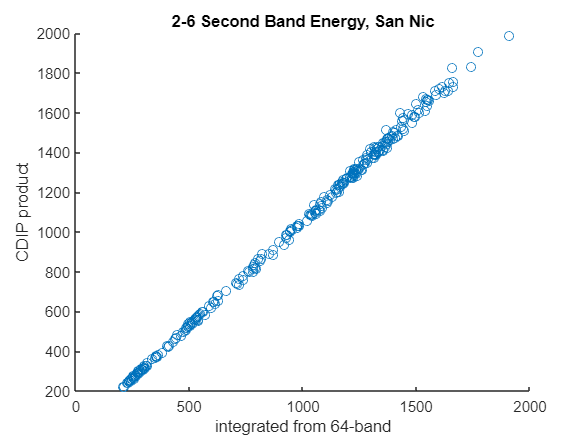

figure(1)
scatter(variance, energies(:,9))
title('2-6 Second Band Energy, San Nic')
xlabel('integrated from 64-band')
ylabel('CDIP product')